# Test Exam F25

## Q1

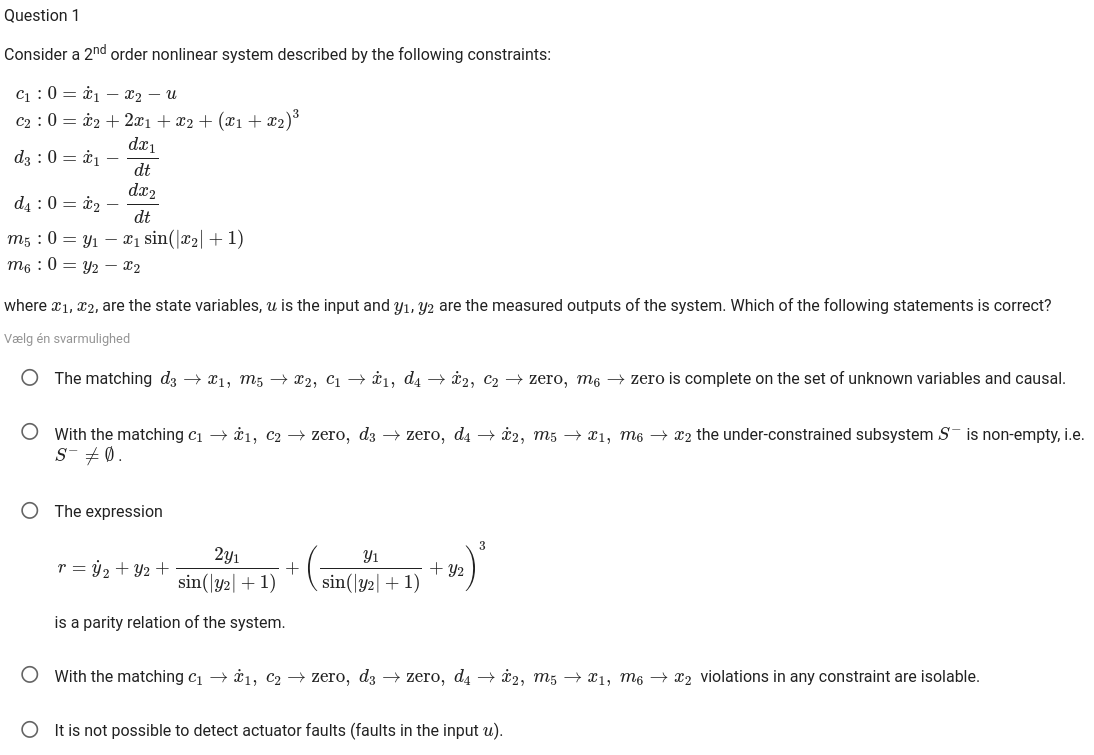

clc
clear all

% Inputs
syms u(t) % Symbolic input declaration
ST_input(1,:) = {u}; % symbolic variable
ST_input(2,:) = {'u\\left(t\\right)'}; % LaTeX expression


% Measurements
syms y1(t) y2(t) % Symbolic measurement declaration
ST_meas(1,:) = {y1, y2}; % symbolic variable
ST_meas(2,:) = {'y1\\left(t\\right)', 'y2\\left(t\\right)'}; % LaTeX expression

% Parameters
syms a % Symbolic parameters declaration
ST_parameters(1,:) = {a}; % symbolic variable
ST_parameters(2,:) = {'a'}; % LaTeX expression

% Unknowns
syms x1(t) x2(t) dx1(t) dx2(t) %Symbolic unknowns declaration
ST_unknowns(1,:) = {x1, x2, dx1, dx2}; % symbolic variable
ST_unknowns(2,:) = {'x1', 'x2', '\dot x_1', '\dot x_2'}; % LaTeX expression

% Enter the constraints of the system
% ST_cons(1.:) comprise the Matlab names of constraints
% ST_cons(2.:) comprise the Latex
% ST_cons(3,:) comprise a cell array list with the expressions of the constraints



ST_cons(1,:) = {'c1','c2','d3','d4','m5','m6'}; % Constraint names
ST_cons(2,:) = {'c_1','c_2','d_3', 'd_4', 'm_5', 'm_6'}; % Constraint latex names
ST_cons(3,:) = {...
                0 == dx1 - x2 - u,...
                0 == dx2 + 2*x1 + x2 + (x1 + x2)^3,...
                0 == dx1 - diff(x1, t),...
                0 == dx2 - diff(x2, t),...
                0 == y1 - x1*sin(abs(x2) + 1),...
                0 == y2 - x2};
% NOTE that "diff(.,t)" is used as the differential operator, D == d/dt.
ST_canfail  = [1:2, 5:6]; % constraint d7-d12 cannot fail
ST_domains  = [1 1 1 1 1 1];


% Automatic incMatrix generation
cons_oneway = {[],[],{x1},{x2},[],[]};
ST_IncMat = sa_incidencematrix(ST_cons,...
    ST_input,ST_meas,...
    ST_unknowns,cons_oneway);

% disp(ST_IncMat)

ST_sys =...
    sa_create(ST_IncMat,ST_cons,...
    ST_input, ST_meas,ST_unknowns,...
    ST_domains, ST_canfail,...
    ST_parameters);

sa_disp(ST_sys);

System with 6 constraint(s), 1 input(s), 2 measurement(s) and
            4 unknown variable(s).


ST_sys=sa_match(ST_sys,'mso'); % alternatively 'rank' MSO

disp('Obtained matching:');

Obtained matching:


sa_disp(ST_sys, 't')

  |     c1 |     c2 |     d3 |     d4 |     m5 |     m6
-------------------------------------------------------
1 |      - |      0 |      - | dx2(t) |  x1(t) |  x2(t)
2 | dx1(t) |      - |      0 |      - |  x1(t) |  x2(t)
3 | dx1(t) |  x1(t) |      0 | dx2(t) |      - |  x2(t)
4 |  x2(t) | dx2(t) | dx1(t) |      0 |  x1(t) |      -



disp('Parity relation symbolic form:')

Parity relation symbolic form:


sa_disp(ST_sys, 's')

Matching 1:
  c2(m5(y1,m6(y2)),m6(y2),d4(m6(y2)))

Matching 2:
  d3(m5(y1,m6(y2)),c1(u,m6(y2)))

Matching 3:
  d3(c2(m6(y2),d4(m6(y2))),c1(u,m6(y2)))

Matching 4:
  d4(c1(u,d3(m5(y1,c1(...)))),c2(m5(y1,c1(...)),c1(u,d3(m5(y1,c1(...))))))



disp('Parity relation analytic form:')

Parity relation analytic form:


sa_disp(ST_sys, 'a')

Matching 1:
  0 == y2(t) + (y2(t) + y1(t)/sin(abs(y2(t)) + 1))^3 + diff(y2(t), t) + (2*y1(t))/sin(abs(y2(t)) + 1)

Matching 2:
  0 == u(t) + y2(t) - diff(y1(t), t)/sin(abs(y2(t)) + 1) + (cos(abs(y2(t)) + 1)*y1(t)*(conj(diff(y2(t), t))*y2(t) + conj(y2(t))*diff(y2(t), t)))/(2*sin(abs(y2(t)) + 1)^2*(conj(y2(t))*y2(t))^(1/2))

Matching 3:
  0 == u(t) + y2(t) + (27*diff(y2(t), t)^3 - 45*y2(t)*diff(y2(t), t)^2 + 6*y2(t)^2*diff(y2(t), t) + 16*diff(y2(t), t) + 21*y2(t)^2*diff(y2(t), t, t) + 16*diff(y2(t), t, t) - 9*y2(t)*diff(y2(t), t)*diff(y2(t), t, t))/(27*diff(y2(t), t)^2 - 54*y2(t)*diff(y2(t), t) + 27*y2(t)^2 + 32) - ((3*(11*y2(t)*diff(y2(t), t) - 3*diff(y2(t), t)^2 + 3*diff(y2(t), t)*diff(y2(t), t, t) - 11*y2(t)*diff(y2(t), t, t)))/(27*diff(y2(t), t)^2 - 54*y2(t)*diff(y2(t), t) + 27*y2(t)^2 + 32) + (12*root(z^3 + 3*z^2*y2(t) + z*(3*y2(t)^2 + 2) + diff(y2(t), t) + y2(t)^3 + y2(t), z, 1)*(diff(y2(t), t) - diff(y2(t), t, t)))/(27*diff(y2(t), t)^2 - 54*y2(t)*diff(y2(t), t) + 27*y2(t)^2 + 32))


pretty(y2(t) + (y2(t) + y1(t)/sin(abs(y2(t)) + 1))^3 + diff(y2(t), t) + (2*y1(t))/sin(abs(y2(t)) + 1))

        /               y1(t)      \3    d              2 y1(t)
y2(t) + | y2(t) + ---------------- |  + -- y2(t) + ----------------
        \         sin(|y2(t)| + 1) /    dt         sin(|y2(t)| + 1)



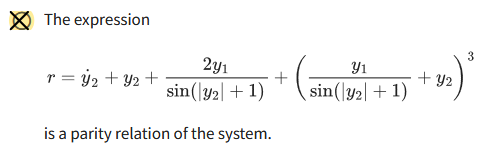

## Q2

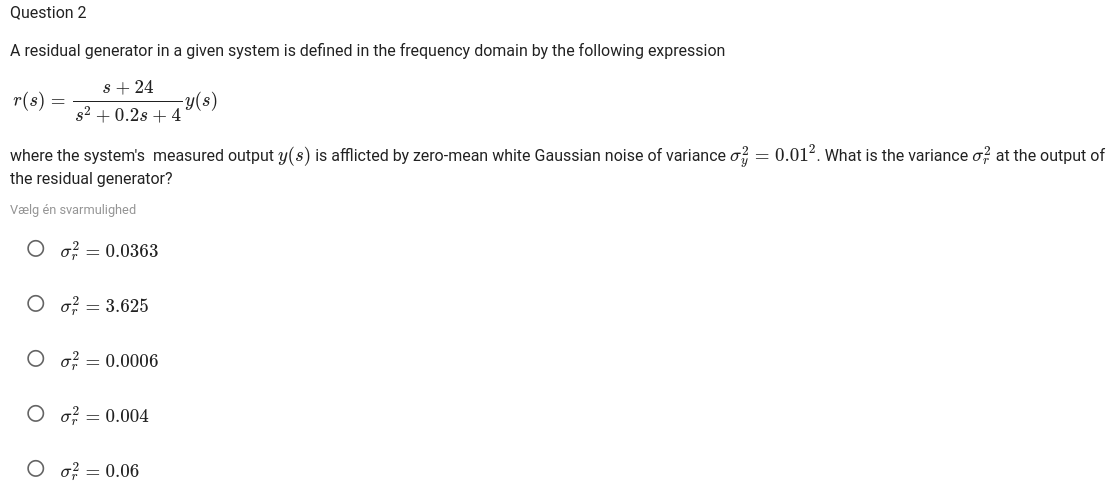

A note on coloured noise in measurements.

% Set up system
r = tf([1 24], [1 0.2 4]);
[A,B,C,D] = tf2ss([1 24], [1 0.2 4]);
sys = ss(A,B,C,D);

sigma_y= 0.01^2;
Qx = lyap(A, B * sigma_y * B');
Qy = C * Qx * C' + D * sigma_y * D'

Qy = 0.0363


$$Q_y =\sigma_r^2 =0\ldotp 0363$$


## Q3

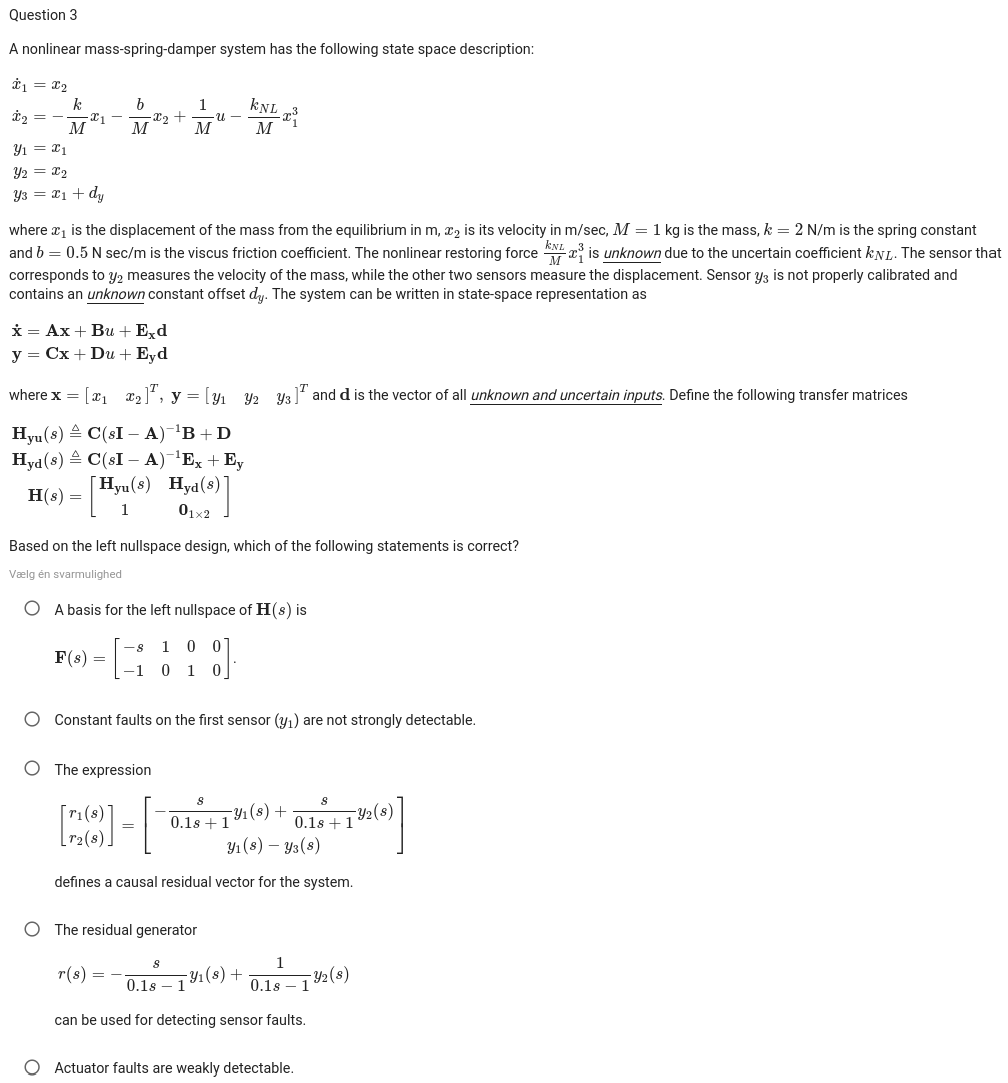

syms k_NL d_y s
M = 1; k = 2; b = 0.5;
A = [0 1
     -k/M -b/M];
B = [0; 1/M];
C = [1, 0;
     0, 1;
     1, 0];
D = 0;
Ex = [0 0; 1/M 0];
Ey = [0 0; 0 0; 0 1];
% General symbolic fault input
syms f1 f2
Fx = sym('f', [2, 2]); % General symbolic faults in state
Fy = sym('fy', [3, 2]); % General symbolic faults in measurement

H_yu = C * inv(s*eye(size(A, 1)) - A) * B + D;
H_yd = C * inv(s*eye(size(A, 1)) - A) * Ex + Ey;
H_yf = C * inv(s*eye(size(A, 1)) - A) * Fx + Fy; % = zeros(3, 2)

H = [H_yu, H_yd;
     eye(1), zeros(1, 2)];
[H_num, H_den] = numden(H(1, 1));
H_tilde = H*H_den;
F = null(H_tilde')'

$$F = \left(\begin{array}{cccc} -s & 1 & 0 & 0 \end{array}\right)$$

$F\left(s\right)\not= \left\lbrack \begin{array}{cccc}
-s & 1 & 0 & 0\\
-1 & 0 & 1 & 0
\end{array}\right\rbrack$-> False

From $F$ we have a causal residual with e.g. a first-order low-pass filter on the form (each element in F is the numerator, with the corresponding y_n, u_n, etc.)

So options a, c, and d are **false**.

% columns = {'y1', 'y2', 'y3', 'u'};
% [num_rows, num_columns] = size(H_yf)

num_rows = 3

num_columns = 2

% fprintf("\nDetectability Analysis:\n");


Detectability Analysis:


% for i = 1:num_faults
%     % Weak detectability: Check rank increase
%     H_aug = [H_yd, H_yf(:, i)];
%     rank_original = rank(H_yd);
%     rank_augmented = rank(H_aug);
% 
%     fprintf("Column #%d (%s)\n", i, columns{i});
%     fprintf(" - Rank(H_yd): %d, Rank([H_yd H_yf(:,%d)]): %d\n", rank_original, i, rank_augmented);
% 
%     if rank_augmented > rank_original
%         fprintf("   -> Weakly detectable\n");
%     else
%         fprintf("   -> Not weakly detectable\n");
%     end
% end

Unrecognized function or variable 'num_faults'.

% % Strong detectability
% n_inputs = size(H, 2);           % Total number of inputs (columns in H)
% n_yf_rows = size(H_yf, 1);       % Number of output rows in H_yf
% extra_inputs = n_inputs - n_yf_rows;
% 
% test_vector = [H_yf(:, i); sym(zeros(extra_inputs, 1))]; % Pad with zeros
% strong_detect = simplify(subs(F * test_vector, s, 0));
% 
% detected = false;
% for j = 1:length(strong_detect)
%     if ~isequal(strong_detect(j), 0)
%         fprintf("   -> Residual %d: strongly detectable\n", j);
%         detected = true;
%     end
% end
% if ~detected
%     fprintf("   -> Not strongly detectable\n");
% end
% for i = 1:num_columns
%     i_rank = rank([H_yd H_yf(:, i)]);
%     disp(sprintf("Column #%d (%s)'s rank: %d", i, columns{i}, rank([H_yd H_yf(:, i)])));
%     if i_rank > rank(H_yd)
%         disp(sprintf("%s is weakly detectable", columns{i}))
%     end
%     strong_detectability = subs(F * [H_yf(:,i); zeros(2)], s, 0);
%     for j = 1:length(strong_detectability)
%         if strong_detectability(j) ~= 0
%             disp(sprintf("Residual %d is strongly detectable", j));
%         end
%     end
%     disp("-------------------------------------")
% end

Actuator faults are not weakly detectable.

Replacing the first row of C with 0, doesn't make it strongly detectable.

## Q4

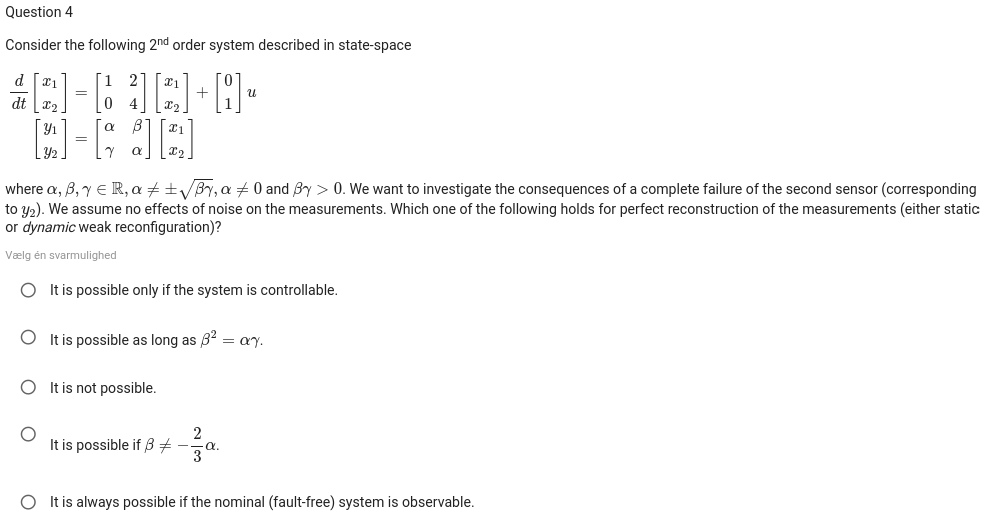

clc; clear all;
syms alpha beta gamma

% assume(alpha ~= sqrt(beta*gamma))
% assume(alpha ~= -sqrt(beta*gamma))
% assume(alpha ~= 0)
assume(beta*gamma > 0)

% assume(beta ~= -2*alpha/3)
% beta = sqrt(alpha*gamma);
alpha = 1;
beta = -1*alpha/3;

A = [1 2
     0 4];
B = [0; 1];
C = [alpha beta
     gamma alpha];

C_f = C(1, :);

% Test if the controlabillity matrix has at least as many
% linearly independant columns as the number of states in the system:
Mc = ctrb(A,B);
if rank(Mc) >= size(A,1)
	disp('System is controllable!');
else
	disp('System is NOT controllable!');
end

System is controllable!



% Static reconfiguration

if (rank(C_f) == rank([C; C_f])) % write the condition for perfect matching
    disp('Perfect matching for sensor fault');
else
    disp('Imperfect matching for sensor fault');
end

Imperfect matching for sensor fault


By analytical approach: option 2 and 4 is incorrect. The  system is controllable, yet perfect matching can't be achieved.

Check for observability, for any value of alpha. The system is only observable if the condition is met.

% Dynamic reconfiguration

% Test if the observability matrix has full column rank,
% and if the system is therefore observable.
Mo = obsv(A, [C_f; C_f*A]);
if rank(Mo) >= size(A,1)
	disp('System is observable!');
else
	disp('System is NOT observable!');
end

System is observable!


## Q5

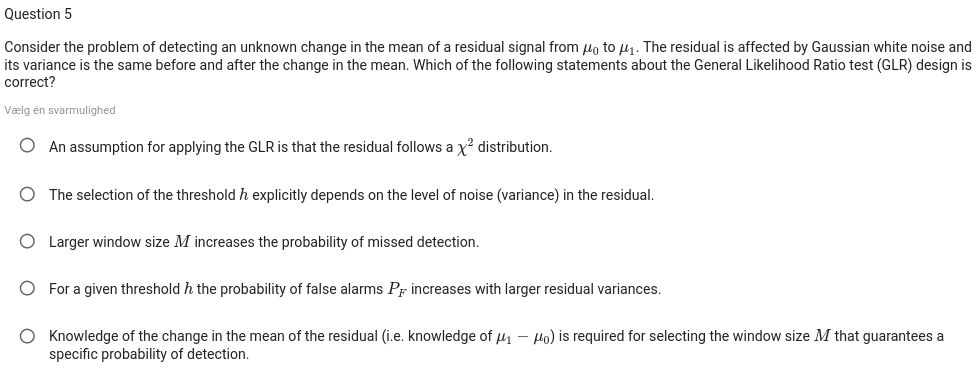

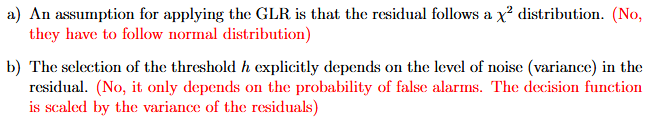

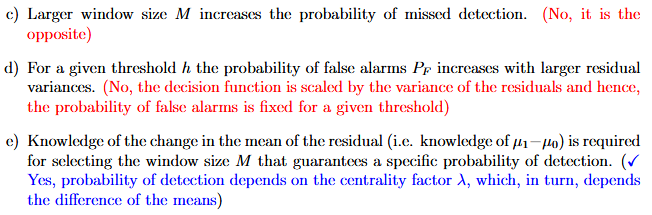

## Q6

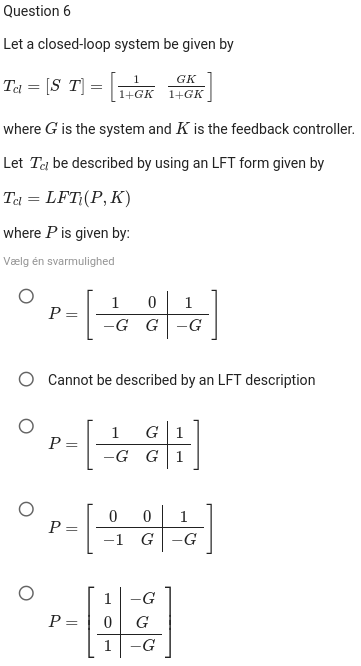

clear all; clc;
syms G K;

% Define the correct P matrix
P = [1 0 1
    -G G -G]

$$P = \left(\begin{array}{ccc} 1 & 0 & 1\\ -G & G & -G \end{array}\right)$$

% Define the submatrices
P11 = P(1, 1:2); P21 = P(1, 3);
P12 = P(2, 1:2); P22 = P(2, 3);

% Compute the LFT: T_cl = P11 + P12*K*(I - P22*K)^(-1)*P21
T_cl = simplify(P11 + P12*K*inv(1-P22*K)*P21);

% Closed-loop transfer function Tcl = [S T]
disp(T_cl)

$$\left(\begin{array}{cc} \frac{1}{G\,K+1} & \frac{G\,K}{G\,K+1} \end{array}\right)$$

## Q7

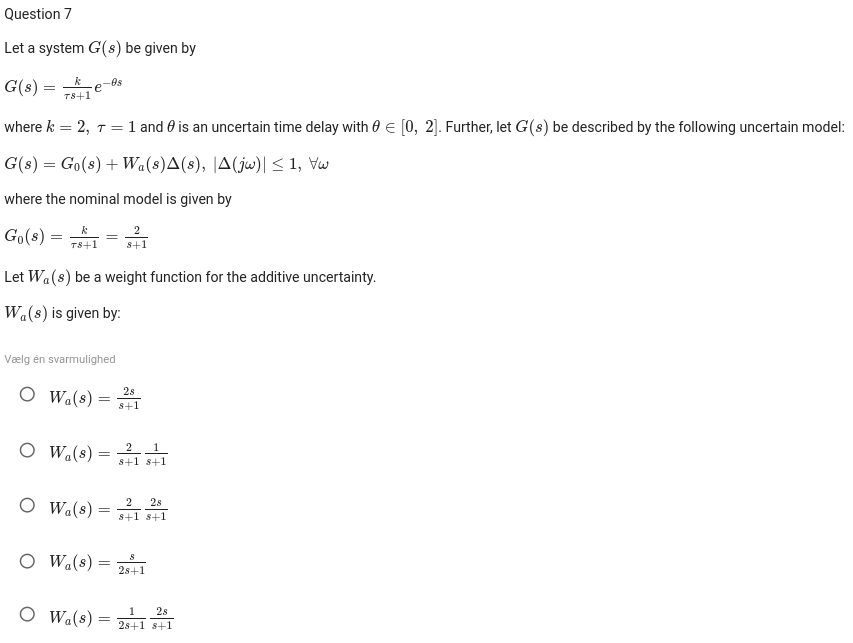

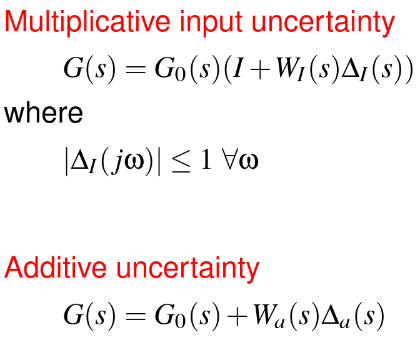(7.26)

Notice connection between multiplicative and additive uncertainty: $G_0 +G_0 W_I =G_0 +W_a \Rightarrow W_a =G_0 W_I$ (confirmed in lecture 1, slide 42/60)

clear; clc;

syms s r_k
k = 2; tau = 1;
theta_max = 2;
G0 = k/(tau*s + 1)

$$G0 = \frac{2}{s+1}$$

W_I = ((1 + (r_k/2))*theta_max*s + r_k) / ((theta_max/2)*s + 1); % from 7.26
W_I = subs(W_I, r_k, 0) % setting r_k = 0. Only thing that produces a match

$$W\_I = \frac{2\,s}{s+1}$$

Wa = G0*W_I

$$Wa = \frac{4\,s}{{\left(s+1\right)}^{2}}$$

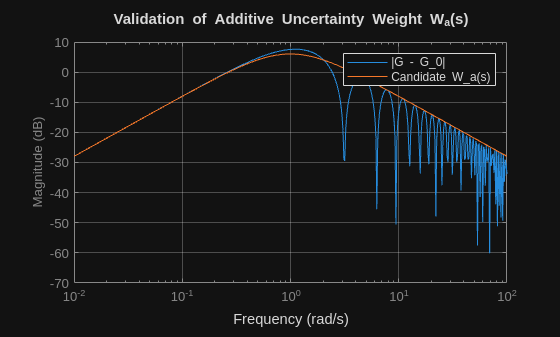

% Try all options, make the candidate W_a fit G - G0. It should align with
% the top curves
s = tf('s');

% Define the nominal model G0
G0 = 2 / (s + 1);

% Define the worst-case time delay
theta = 2;
G = G0 * exp(-theta * s);

% Define the additive uncertainty
Delta_a = G - G0;

% Frequency range for analysis
w = logspace(-2, 2, 500);
[mag, ~] = bode(Delta_a, w);
mag = squeeze(mag);

% Use 'fitmagfrd' or manual curve fitting if you have Robust Control Toolbox
% We'll define a candidate Wa(s) and compare
Wa = (2/(s + 1)) * ((2*s)/(s + 1));

% Plot to check if Wa upper-bounds Delta_a
figure;
bodemag(Delta_a, Wa, w);
legend('|G - G_0|', 'Candidate W_a(s)');
grid on; 
title('Validation of Additive Uncertainty Weight W_a(s)');

## Q8

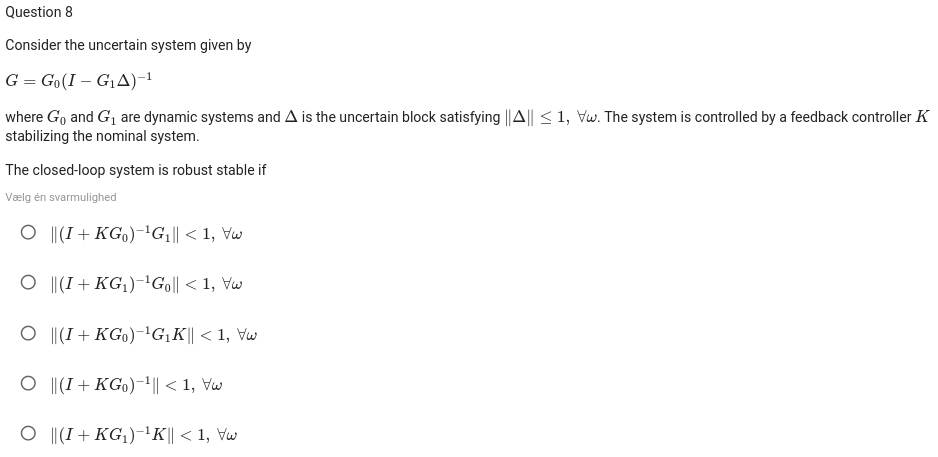

Figure 8.5 (e)

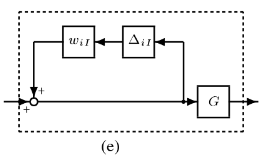'

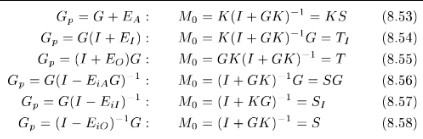

$G_p =G{\left(I-w_{\textrm{iI}} \right)}^{-1} G$, where $G=G_0$ and $w_{\textrm{iI}} =G_1$.

So the system is a *inverse multiplicative input uncertainty.*

Check for closed-loop system RS.

We have $M_0$ from 8.57, which we use to find $M$

SEE OTHER EXAMS.

## Q9

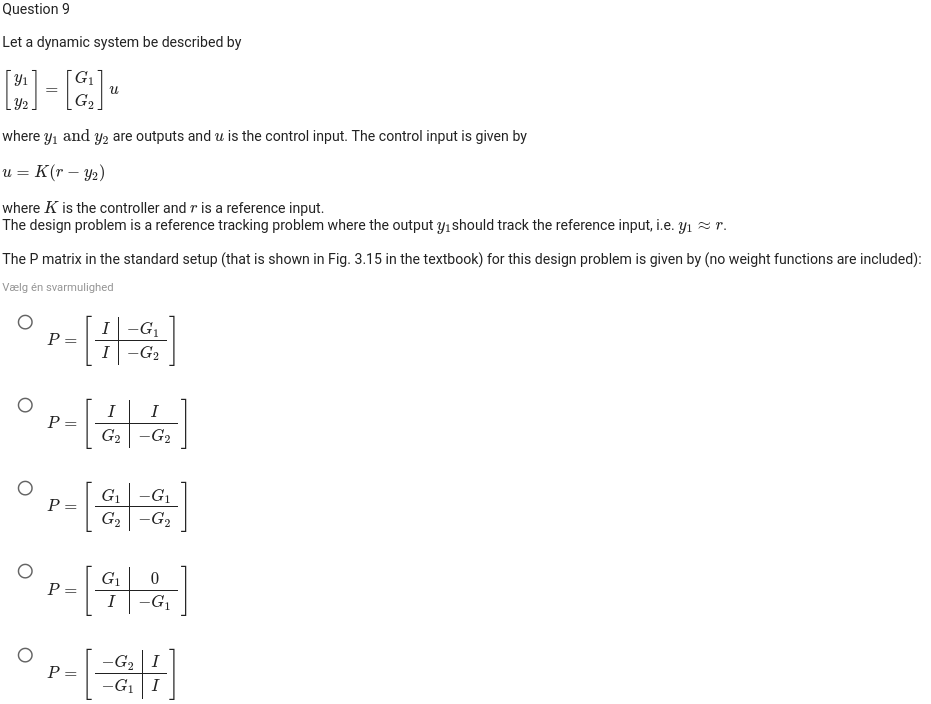

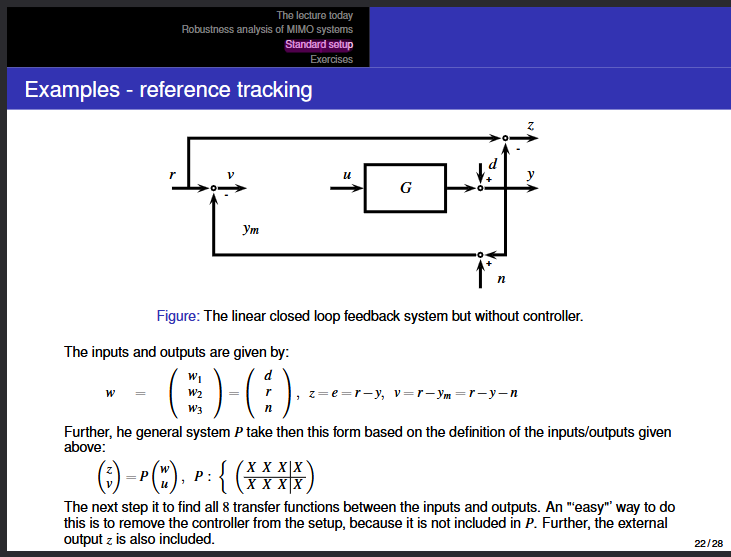

Reference tracking example: no disturbances or noise. Split 'G' in two, like stated in $\left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
G_1 \\
G_2 
\end{array}\right\rbrack u$

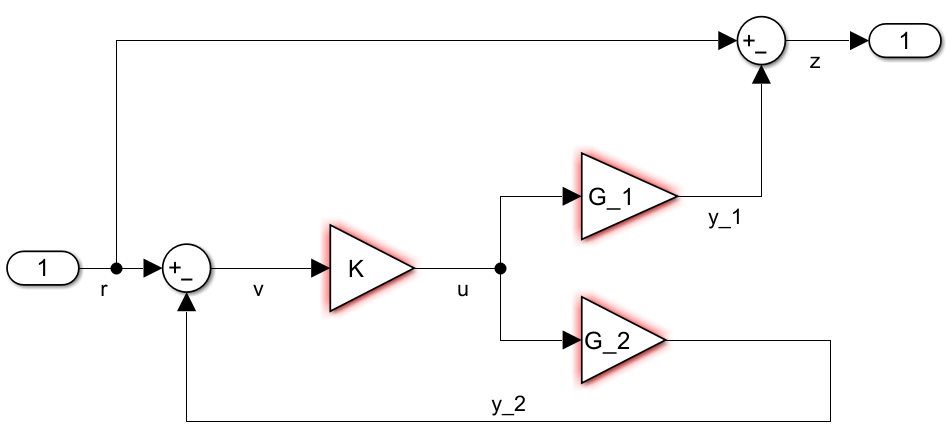

Trace what 'z' and 'v' is equal:


$$\left\lbrack \begin{array}{c}
z\\
v
\end{array}\right\rbrack =P\left\lbrack \begin{array}{c}
r\\
u
\end{array}\right\rbrack$$
    
$$\left\lbrack \begin{array}{c}
z\\
v
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
I & -G_1 \\
I & -G_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r\\
u
\end{array}\right\rbrack$$


## Q10

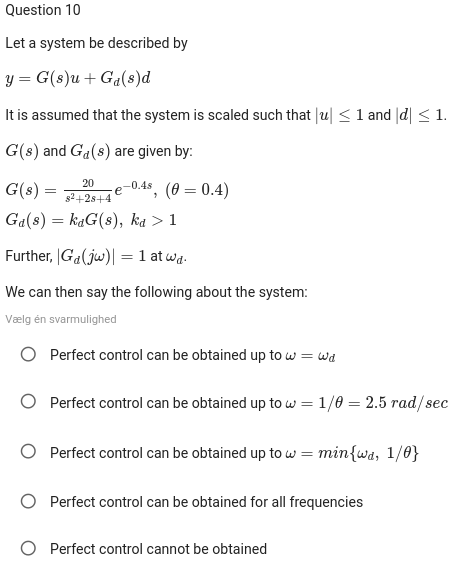


$$\textrm{PC}:|G^{-1} G_d |<1\Leftrightarrow |G_d |<|G|$$


As $G_d$ is a multiple of $G$ (with a constant >1), it will always be larger, thus PC cannot be realized.